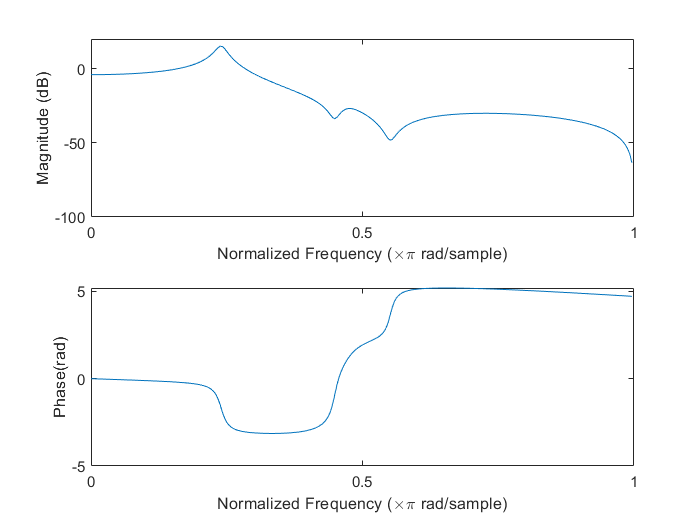

syms z
n = [0.1 0.1 0.18 0.18 0.09 0.09];
d = [1 -1.5 2.2 -1.5 0.8 0.18];

[h,w] = freqz(n,d,256);
figure
subplot(2,1,1)
plot(w/pi,20*log10(abs(h)))
ax = gca;
ax.YLim = [-100 20];
ax.XTick = 0:.5:2;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

subplot(2,1,2)
plot(w/pi,phase(h))
ax = gca;
ax.XTick = 0:.5:2;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase(rad)')

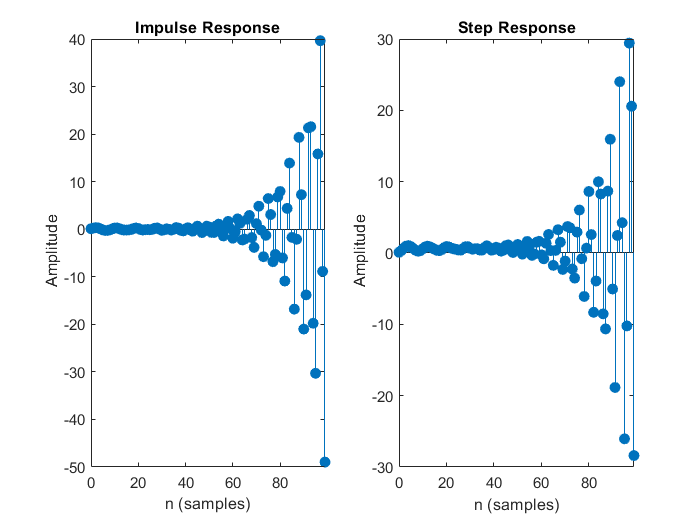



figure
subplot(1,2,1)
impz(n,d,100)
subplot(1,2,2)
stepz(n,d,100)